clear all;

buffer_size = 512;
sampling_freq = 29900;

out = sim("main.slx");

sim_time = out.tout;
fl_signals = out.FloatingPoint.signals;

fl_fft_signal = fl_signals(1).values;
fl_thd_signal = fl_signals(2).values;
fl_input_signal = fl_signals(3).values;

fp_signals = out.FixedPoint.signals;

fp_fft_signal = fl_signals(1).values;
fp_thd_signal = fl_signals(2).values;
fp_input_signal = fl_signals(3).values;

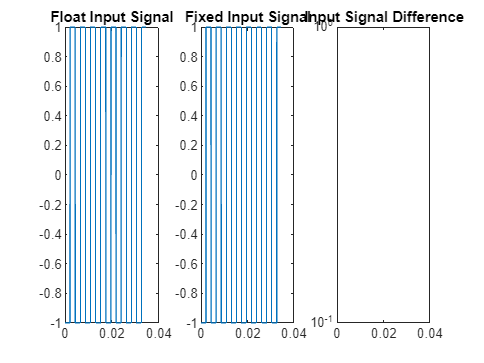

figure
subplot(1, 3, 1);
plot(sim_time, fl_input_signal);
title("Float Input Signal");
subplot(1, 3, 2);
plot(sim_time, fp_input_signal);
title("Fixed Input Signal");
subplot(1, 3, 3);
semilogy(sim_time, abs(fp_input_signal - fp_input_signal));
title("Input Signal Difference");

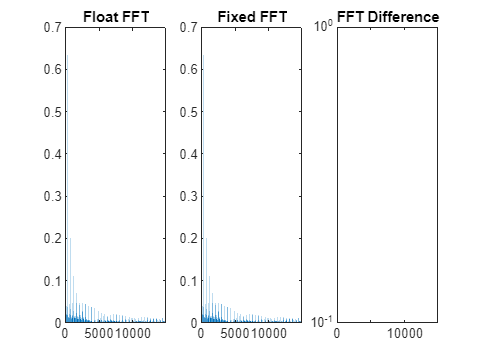



lx = (length(arbitrary_slice));
half = ceil(lx/2);
fx = (0:half-1)*(sampling_freq/buffer_size);

fl_arbitrary_slice = fl_fft_signal(:, buffer_size+1);
fp_arbitrary_slice = fp_fft_signal(:, buffer_size+1);

figure
subplot(1, 3, 1);
bar(fx, abs(fl_arbitrary_slice(1:half)))
title("Float FFT");
subplot(1, 3, 2);
bar(fx, abs(fp_arbitrary_slice(1:half)))
title("Fixed FFT");
subplot(1, 3, 3);
semilogy(fx, abs(fl_arbitrary_slice(1:half) - fp_arbitrary_slice(1:half)));
title("FFT Difference");


disp(fl_thd_signal(513))

    3.7747



disp(fp_thd_signal(513))

    3.7747

